% knn
% MLP数据，角度作为输出
dataFolder = 'dataset/';  % 你的数据目录
fileList = dir(fullfile(dataFolder, '*.mat'));

N_sample = 100;
XTrain = [];
YTrain = [];
XValidation = [];
YValidation = [];
train_number = 126;validation_number = 2;
cn_train = zeros(train_number*N_sample, P*Q*2);
cn_val = zeros(validation_number*N_sample, P*Q*2);


for i = 1:10
%     data = load(fullfile(dataFolder, fileList(i).name));

    filename = sprintf("dataset\\G_complex_4.17_%d", i);
    data = load(filename + ".mat");
%     points = data.points;
%     points = data.points .* [Lx, Ly] - [Lx/2, Ly/2];
    XTrain = [XTrain; data.ln_all(:, 1:train_number).'];
    YTrain = [YTrain; data.G_complex_all(:, 1:train_number).'];
    XValidation = [XValidation; data.ln_all(:, train_number+1:train_number+validation_number).'];
    YValidation = [YValidation; data.G_complex_all(:, train_number+1:train_number+validation_number).'];
end

AEP_predicted = knn_regression(XTrain, YTrain, XValidation(1,:), 5);

正在将数据插值到 uv 网格...


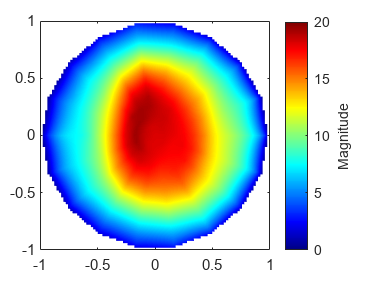

已生成 uv 域插值 pcolor 图。


plot_inUV(abs(AEP_predicted), angles_uv);

正在将数据插值到 uv 网格...


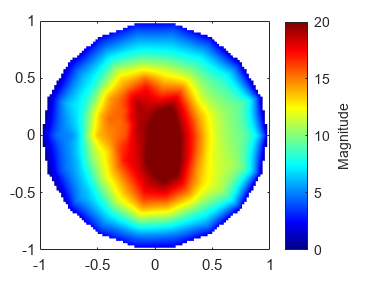

已生成 uv 域插值 pcolor 图。


plot_inUV(abs(YValidation(1,:)), angles_uv);

正在将数据插值到 uv 网格...


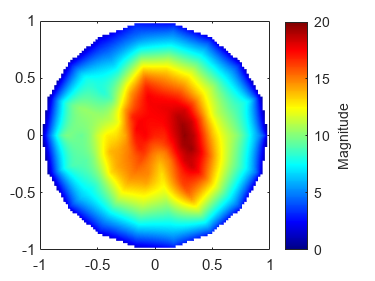

已生成 uv 域插值 pcolor 图。


plot_inUV(abs(YTrain(194,:)), angles_uv);

function predicted_AEP = knn_regression(training_data, training_AEP, test_instance, k)
    % Calculate distances between test instance and all training instances
    num_training = size(training_data, 1);
    distances = zeros(num_training, 1);
    
    for i = 1:num_training
        % Euclidean distance
        distances(i) = sqrt(sum((training_data(i,:) - test_instance).^2));
    end
    
    % Sort distances and get indices
    [sorted_distances, indices] = sort(distances);
    
    % Get the k nearest neighbors and their labels
    k_nearest_indices = indices(1:k);
    k_nearest_labels = training_AEP(k_nearest_indices, :);
    sum_k = sum(sorted_distances(1:k));
    predicted_AEP = zeros(1,370);
    for i = 1:k
        predicted_AEP = predicted_AEP + sorted_distances(i) / sum_k * abs(k_nearest_labels(i,:));
    end
end